modelFolder = "C:\UAlbany\2026\Spring 2026\ECE 465 - Machine Learning\ML_Project\project_Demo";

load(fullfile(modelFolder, "speechCommandModelv5.mat"));
load(fullfile(modelFolder, "multi_speaker_model.mat"));

% Now taking own voice recording and predicting
disp("Start speaking")

Start speaking


recObj = audiorecorder(16000,16,1);
recordblocking(recObj,1);
disp("Recording finished")

Recording finished


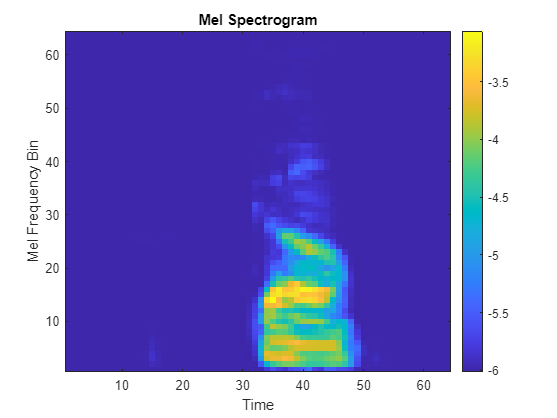


audio = getaudiodata(recObj);
audiowrite("testRecording.wav",audio,16000);

fs = 16000;

audio = audio ./ (max(abs(audio)) + 1e-6);
sound(audio,fs);

melSpec = melSpectrogram(audio, fs, 'NumBands',64);
melSpec = log10(melSpec + 1e-6);
melSpec = imresize(melSpec,[64 64]);
inputImage = reshape(melSpec,[64 64 1 1]);

figure;
imagesc(melSpec);
axis xy;
xlabel("Time");
ylabel("Mel Frequency Bin");
title("Mel Spectrogram");
colorbar;


[predictedWord, scores] = classify(net,inputImage);

%disp("First Guess: ");
%disp(predictedWord);

%sets confidence threshold so that if its <75% confident it will just
%classify it as unknown
threshold = 0.75;
maxScore = max(scores);

if maxScore < threshold
    predictedWord = categorical("unknown");
end

fprintf("Predicted word: %s\n", string(predictedWord));

Predicted word: stop



fprintf("Confidence: %.1f%%\n", maxScore*100);

Confidence: 96.0%



if string(predictedWord) == "go"
    predictedSpeaker = predictSpeakerGMM(audio, fs, models, mu, sigma);
    
    disp("Command 'go' detected. Voice recognition enabled.");
    fprintf("Predicted speaker: %s\n", predictedSpeaker);
end


function predictedSpeaker = predictSpeakerGMM(audio, fs, models, mu, sigma)

    % Convert stereo to mono if needed
    if size(audio, 2) > 1
        audio = mean(audio, 2);
    end

    % Resample to 16 kHz if needed
    targetFs = 16000;
    if fs ~= targetFs
        audio = resample(audio, targetFs, fs);
        fs = targetFs;
    end

    % Normalize volume
    audio = audio / (max(abs(audio)) + eps);

    % Extract MFCC features, matching the MFCC training script
    feats = mfcc(audio, fs, ...
        "NumCoeffs", 13, ...
        "WindowLength", round(0.025 * fs), ...
        "OverlapLength", round(0.015 * fs));

    % Remove invalid rows
    feats = feats(all(isfinite(feats), 2), :);

    % Normalize using training statistics
    feats = (feats - mu) ./ sigma;

    names = fieldnames(models);
    scores = zeros(length(names), 1);

    for i = 1:length(names)
        scores(i) = sum(log(pdf(models.(names{i}), feats) + 1e-10));
    end

    disp("GMM speaker scores:");
    for i = 1:length(names)
        fprintf("%s: %.2f\n", names{i}, scores(i));
    end

    [sortedScores, sortedIdx] = sort(scores, "descend");

    bestScore = sortedScores(1);
    secondBestScore = sortedScores(2);
    scoreGap = bestScore - secondBestScore;

    speakerThreshold = 10;   % tune after testing

    if scoreGap < speakerThreshold
        predictedSpeaker = "unknown";
    else
        predictedSpeaker = string(names{sortedIdx(1)});
    end

    %fprintf("Speaker score gap: %.2f\n", scoreGap);

end